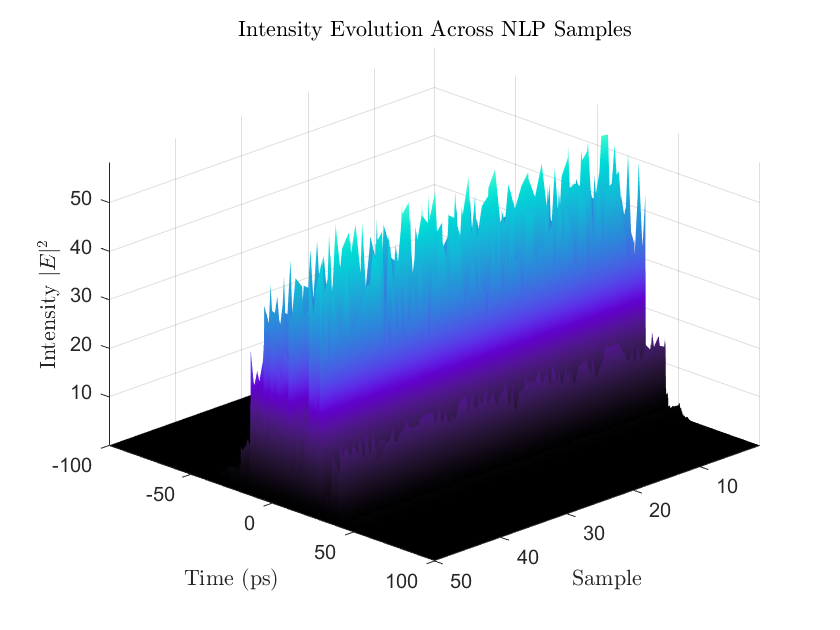

clear; clf; close all

dataDir = 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';
cd(dataDir)

numFiles = 50;

for k = 1:numFiles
    % build the filename
    fname = sprintf('NLPx%d.csv', k);
    
    % read it
    M = readmatrix(fname);
    
    % on the first pass, pull out the time vector and pre-allocate
    if k==1
        t_ps     = M(:,1);
        nSamples = numel(t_ps);
        I_all    = zeros(nSamples, numFiles);
    end
    
    % extract the two field components (note: column 3 for E_Px, not 2)
    E_Nx = M(:,2);
    E_Px = M(:,3);
    
    % compute intensity and store
    I_all(:,k) = abs(E_Nx).^2 + abs(E_Px).^2;
end

% === after the loop ===
% build a grid of (sample, time)
[SampleIdx, TimeGrid] = meshgrid(1:numFiles, t_ps);

% plot surface
figure;
surf(SampleIdx, TimeGrid, I_all, 'EdgeAlpha', 0.001)
view(135,30)         % adjust as you like
xlabel('Sample', "Interpreter","latex")   % NLP index
ylabel('Time (ps)', "Interpreter","latex")
zlabel('Intensity $|E|^2$', "Interpreter","latex")
title('Intensity Evolution Across NLP Samples', "Interpreter","latex")

% make it pretty
colormap(slanCM('cosmic'))
shading interp
axis tight
grid on